clear;clc;close all;
E = 200e9;
A1 = 1e-4;
A2 = sqrt(2)/2 * A1;
l = 0.2;
k31 = getK(E , A1 , l , 0);
k41 = getK(E , A2 , sqrt(2)*l , pi/4);
k12 = getK(E , A1 , l , -pi/2);
k32 = getK(E , A2 , sqrt(2)*l , -pi/4);
k42 = getK(E , A1 , l , 0);
k34 = getK(E , A1 , l , -pi/2);

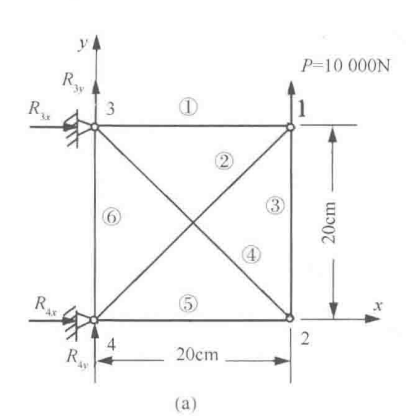

K = zeros(8,8);
K = Addpole(K , k31 , 3 , 1);
K = Addpole(K , k41 , 4 , 1);
K = Addpole(K , k12 , 1 , 2);
K = Addpole(K , k32 , 3 , 2);
K = Addpole(K , k42 , 4 , 2);
K = Addpole(K , k34 , 3 , 4);
K

K = 	1.0e+08 *

    1.2500    0.2500   -0.0000    0.0000   -1.0000         0   -0.2500   -0.2500
    0.2500    1.2500    0.0000   -1.0000         0         0   -0.2500   -0.2500
   -0.0000    0.0000    1.2500   -0.2500   -0.2500    0.2500   -1.0000         0
    0.0000   -1.0000   -0.2500    1.2500    0.2500   -0.2500         0         0
   -1.0000         0   -0.2500    0.2500    1.2500   -0.2500   -0.0000    0.0000
         0         0    0.2500   -0.2500   -0.2500    1.2500    0.0000   -1.0000
   -0.2500   -0.2500   -1.0000         0   -0.0000    0.0000    1.2500    0.2500
   -0.2500   -0.2500         0         0    0.0000   -1.0000    0.2500    1.2500
